clear; clc; close all

width = 1.5 ; % Line thickness
lsize = 12 ; tsize = 14 ; legsize = 9 ; msize = 8 ; % Font size in plots, label, %title, %legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultlegendInterpreter','latex');

% COLOURS - MaTLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load('point1.mat')
point

point = struct with fields:
       Mach: [5×12×7 double]
    Spacing: [5×12×7 double]
    Stagger: [5×12×7 double]
      Angle: [5×12×7 double]
     output: [1×1 struct]
    output1: [1×1 struct]



%[Machs,Spacings,Stagger] = meshgrid([Machs,Spacings,Stagger]);

Machs = [1.4,1.5,1.6,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5];
Spacings = [0.25,0.375,0.5,0.625,0.75];
Staggers = [-0.5,-0.25,-0.1,0,0.1,0.25,0.5];
% In Gmsh this was defined as: 
    % stag = -0.1*c;
    % Point(n) = {(point-stag, H/2, 0, meshouteruf};
    % Thus a negative stagger makes a positive change i.e. -x=aft, +x=fore
    % Ideally we want i.e. +x=aft, -x=fore, we will convert later
    
% LOAD IN VALUES (CONVERT MOMENT DIRECTION)
cm = -point.output1.cm;         % Minus sign for right-to-left hand
cd = point.output1.cd;
cl = point.output1.cl;
cmMa2 = -point.output1.moment;  % Minus sign for right-to-left hand
cdMa2 = point.output1.dragm;
clMa2 = point.output1.lift;

% Corrections
% point at (0.5H,2.2Ma,0.1x)
cdMa2(3,9,5) = 0.33;
cd(3,9,5) = cdMa2(3,9,5)./(1.8^2);
% point at (0.75H,1.8Ma,-0.1x)
cdMa2(5,5,3) = 0.2;
cd(5,5,3) = cdMa2(5,5,3)./(1.8^2);
% point at (0.375H,2.1Ma,-0.25x)
cdMa2(2,8,2) = 0.1200;
cd(2,8,2) = cdMa2(3,5,2)./(2.1^2);

LoverD = cl./cd;

[cds,cdc,started_locations,choked_locations] = cd_isstarted(cd,0.060);
[cms,cmc]=splitmatrix(cm,started_locations,choked_locations);
[cls,clc]=splitmatrix(cl,started_locations,choked_locations);
[cmMa2s,cmMa2c]=splitmatrix(cmMa2,started_locations,choked_locations);
[cdMa2s,cdMa2c]=splitmatrix(cdMa2,started_locations,choked_locations);
[clMa2s,clMa2c]=splitmatrix(clMa2,started_locations,choked_locations);
[LoverDs,LoverDc]=splitmatrix(LoverD,started_locations,choked_locations);

X=point.Mach;
Y=point.Spacing;
Z=-(point.Stagger);                           % Minus sign for conventional direction
Staggers = -[-0.5,-0.25,-0.1,0,0.1,0.25,0.5]; % Minus sign for conventional direction
viewangle=[79.693 10.462];

cmap = parula;

figure
FancyScatter3s(cmMa2s,X,Y,Z,Spacings,Staggers,viewangle)

ans = 1

hold on
FancyScatter3c(cmMa2c,X,Y,Z,Spacings,Staggers,viewangle,width)

ans = 1

grid on; box on; hold on
%title({'$C_{m}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle)
caxis

ans =    -0.4086    0.4657


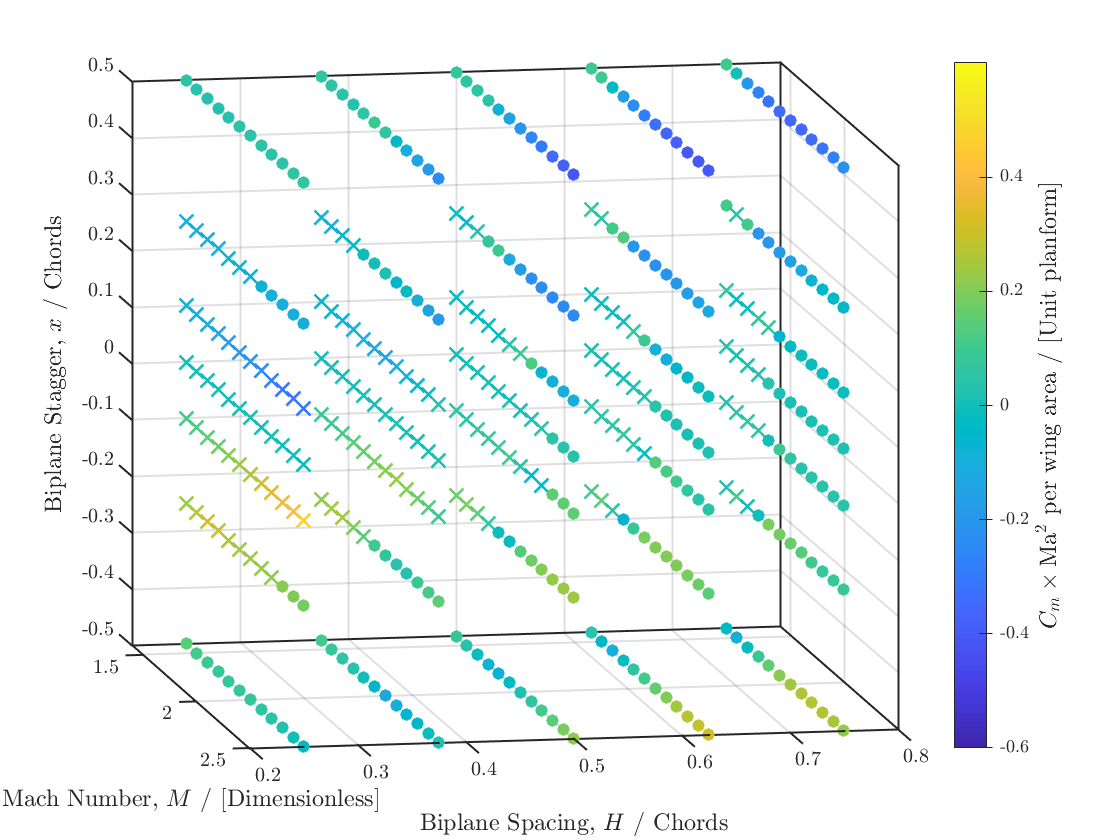

caxis([-0.6 0.6])
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
set(c, 'ylim', [-0.6 0.6]); % set your range here
colormap(cmap); % apply new colormap
ylabel(c,'$C_{m}\times\textrm{Ma}^2$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
H=gca; H.LineWidth=1; hold off
hold off
saveas(gcf,'alfa1_cmMa2_scatter.png')


figure
FancyScatter3s(cdMa2s,X,Y,Z,Spacings,Staggers,viewangle)

ans = 1

hold on
FancyScatter3c(cdMa2c,X,Y,Z,Spacings,Staggers,viewangle,width)

ans = 1

grid on; box on; hold on
%title({'$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle)
caxis

ans =     0.0353    0.7131


caxis([0 0.8])
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
set(c, 'ylim', [0 0.8]); % set your range here
colormap(cmap); % apply new colormap
ylabel(c,'$C_{D_{\textrm{Wave}}}\times\textrm{Ma}^2$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
H=gca; H.LineWidth=1; hold off
hold off
saveas(gcf,'alfa1_cdMa2_scatter.png')

figure
FancyScatter3s(clMa2s,X,Y,Z,Spacings,Staggers,viewangle)

ans = 1

hold on
FancyScatter3c(clMa2c,X,Y,Z,Spacings,Staggers,viewangle,width)

ans = 1

grid on; box on; hold on
%title({'$C_{L}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle)
caxis

ans =    -0.4163    0.8971


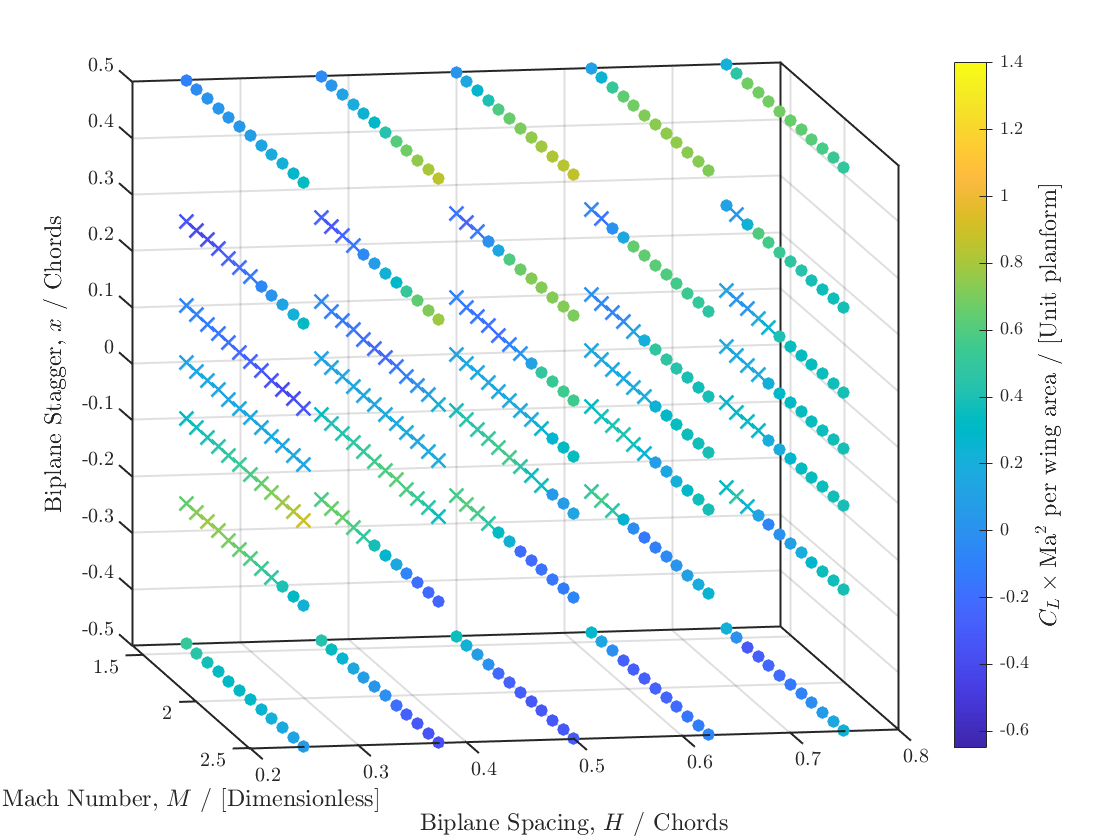

caxis([-0.65 1.4])
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
set(c, 'ylim', [-0.65 1.4]); % set your range here
colormap(cmap); % apply new colormap
ylabel(c,'$C_{L}\times\textrm{Ma}^2$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
H=gca; H.LineWidth=1; hold off
hold off
saveas(gcf,'alfa1_clMa2_scatter.png')


figure
FancyScatter3s(cms,X,Y,Z,Spacings,Staggers,viewangle)

ans = 1

hold on
FancyScatter3c(cmc,X,Y,Z,Spacings,Staggers,viewangle,width)

ans = 1

grid on; box on; hold on
%title({'\textbf{Moment Coefficient} $C_{m}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle)
caxis

ans =    -0.0980    0.1233


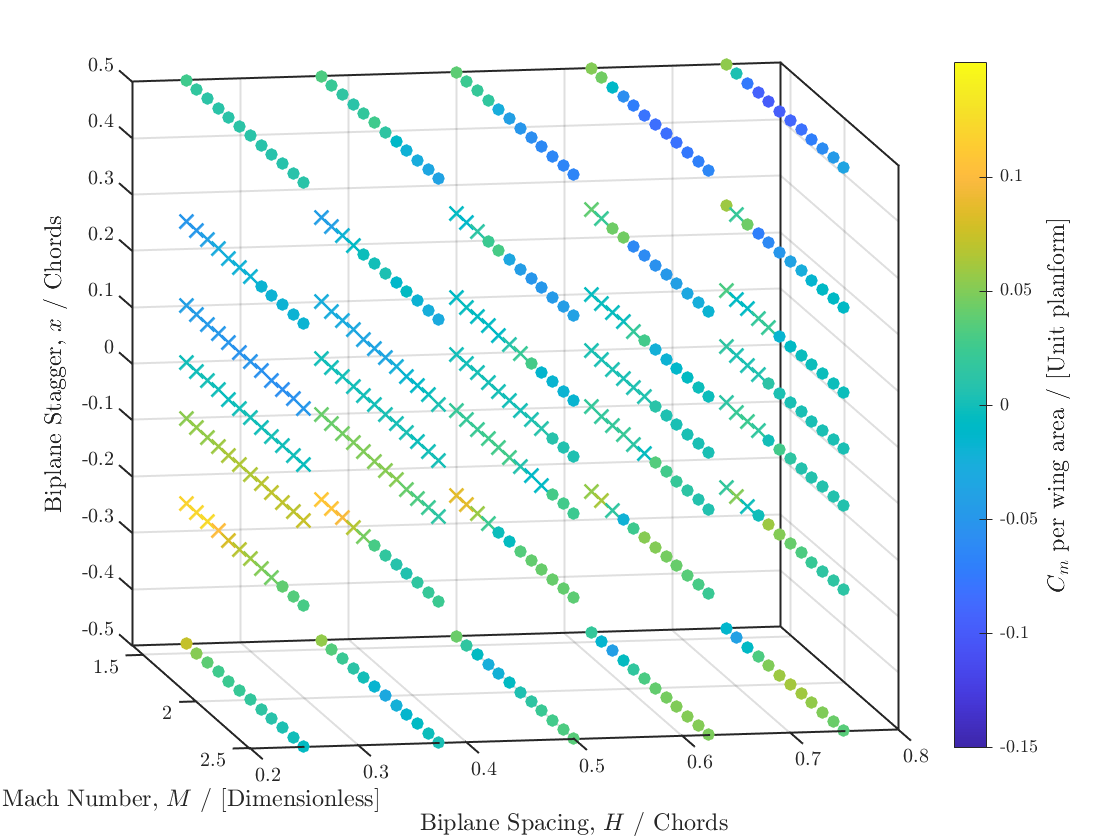

caxis([-0.15 0.15])
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
set(c, 'ylim', [-0.15 0.15]); % set your range here
colormap(cmap); % apply new colormap
ylabel(c,'$C_{m}$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
H=gca; H.LineWidth=1; hold off
hold off
saveas(gcf,'alfa1_cm_scatter.png')


figure
FancyScatter3s(cds,X,Y,Z,Spacings,Staggers,viewangle)

ans = 1

hold on
FancyScatter3c(cdc,X,Y,Z,Spacings,Staggers,viewangle,width)

ans = 1

grid on; box on; hold on
%title({'\textbf{Wave Drag Coefficient} $C_{D_\textrm{Wave}}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle)
caxis

ans =     0.0092    0.1351


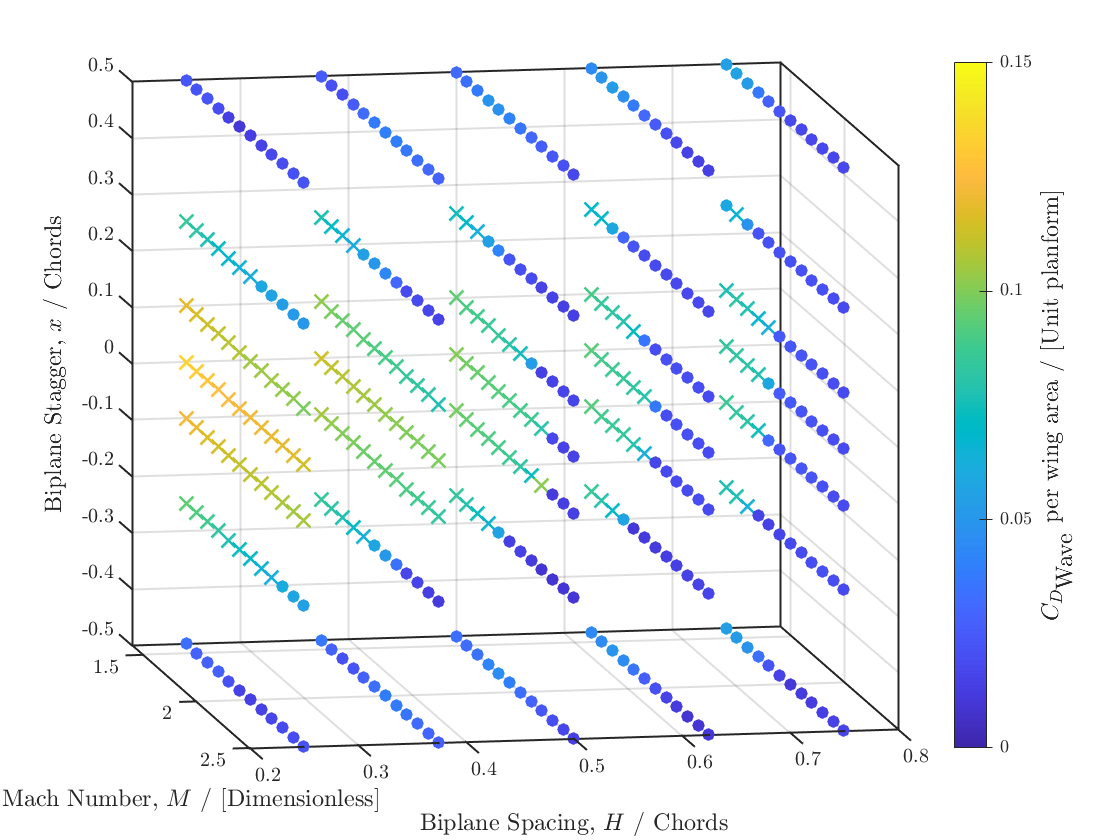

caxis([0 0.15])
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
set(c, 'ylim', [0 0.15]); % set your range here
colormap(cmap); % apply new colormap
ylabel(c,'$C_{D_{\textrm{Wave}}}$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
H=gca; H.LineWidth=1; hold off
hold off
saveas(gcf,'alfa1_cd_scatter.png')


figure
FancyScatter3s(cls,X,Y,Z,Spacings,Staggers,viewangle)

ans = 1

hold on
FancyScatter3c(clc,X,Y,Z,Spacings,Staggers,viewangle,width)

ans = 1

grid on; box on; hold on
%title({'\textbf{Lift Coefficient} $C_{L}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle)
caxis

ans =    -0.1850    0.3264


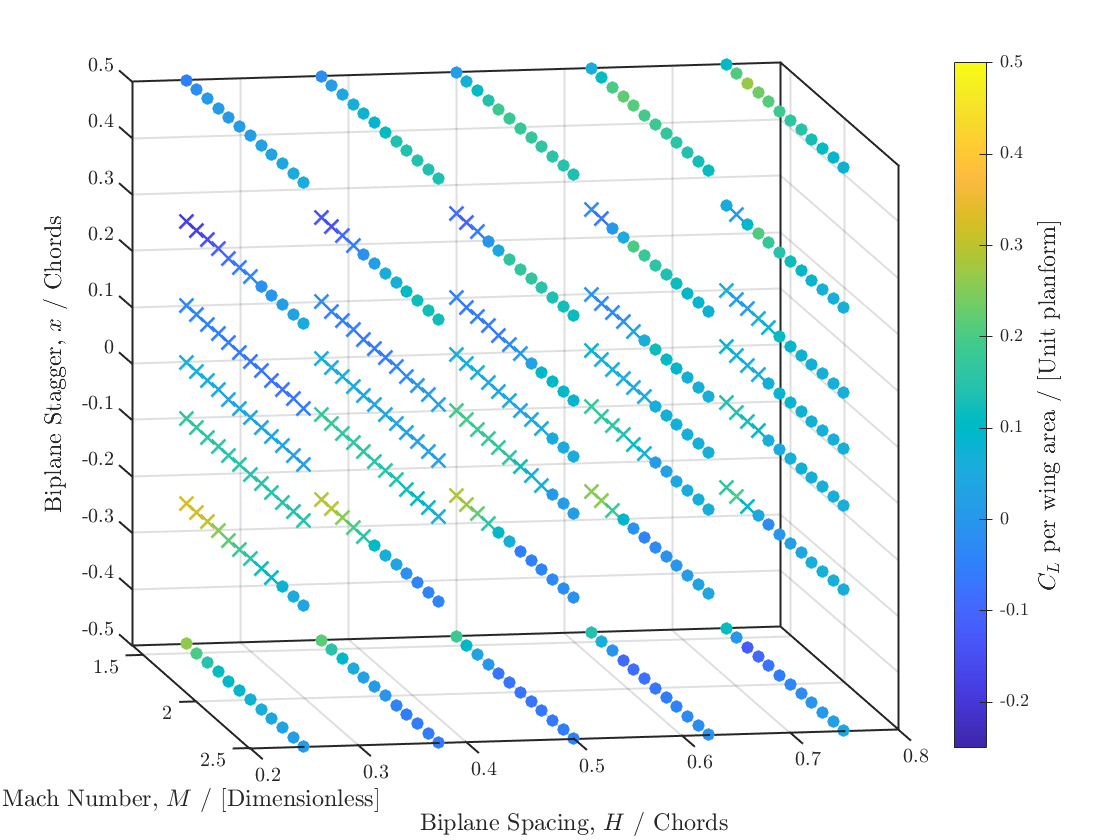

caxis([-0.25 0.5])
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
set(c, 'ylim', [-0.25 0.5]); % set your range here
colormap(cmap); % apply new colormap
ylabel(c,'$C_{L}$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
H=gca; H.LineWidth=1; hold off
hold off
saveas(gcf,'alfa1_cl_scatter.png')


figure
FancyScatter3s(LoverDs,X,Y,Z,Spacings,Staggers,viewangle)

ans = 1

hold on
FancyScatter3c(LoverDc,X,Y,Z,Spacings,Staggers,viewangle,width)

ans = 1

grid on; box on; hold on
%title({'\textbf{Lift-to-Drag Ratio} $\frac{L}{D}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle)
caxis

ans =    -4.0269    9.6328


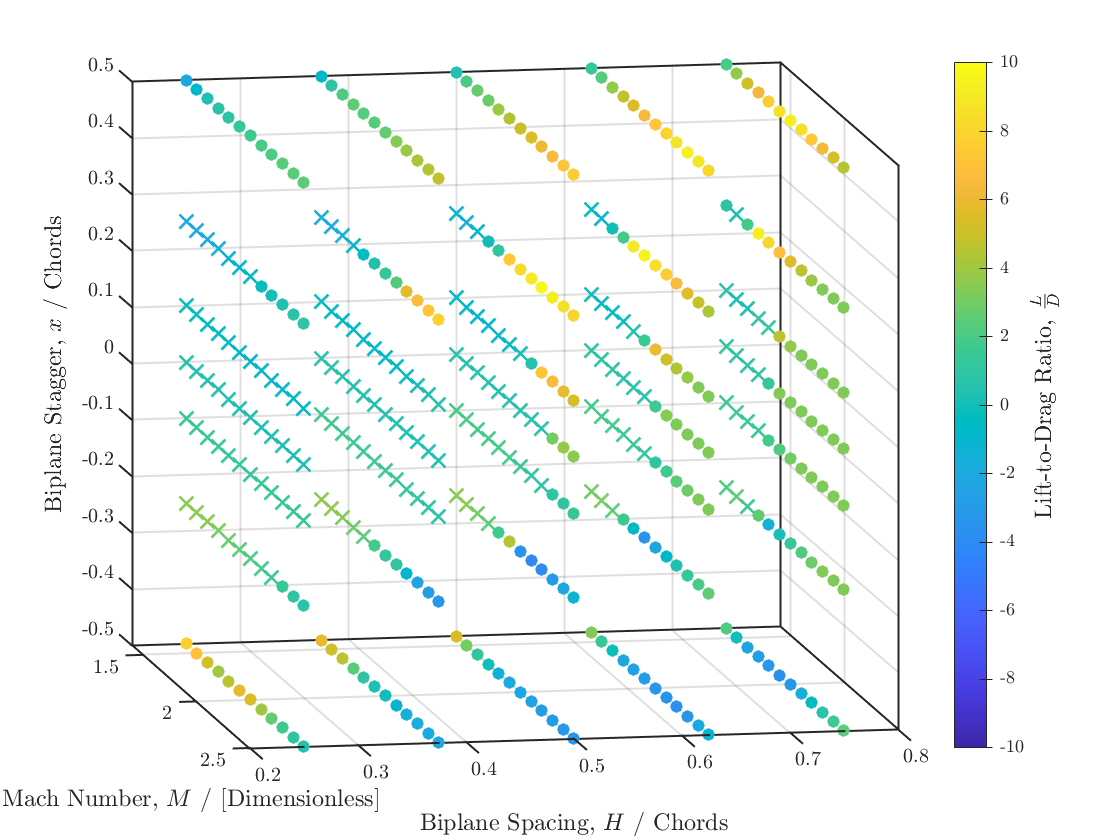

caxis([-10 10])
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
set(c, 'ylim', [-10 10]); % set your range here
colormap(cmap); % apply new colormap
ylabel(c,'Lift-to-Drag Ratio, $\frac{L}{D}$','Interpreter','latex','FontSize',lsize)
H=gca; H.LineWidth=1; hold off
hold off
saveas(gcf,'alfa1_loverd_scatter.png')

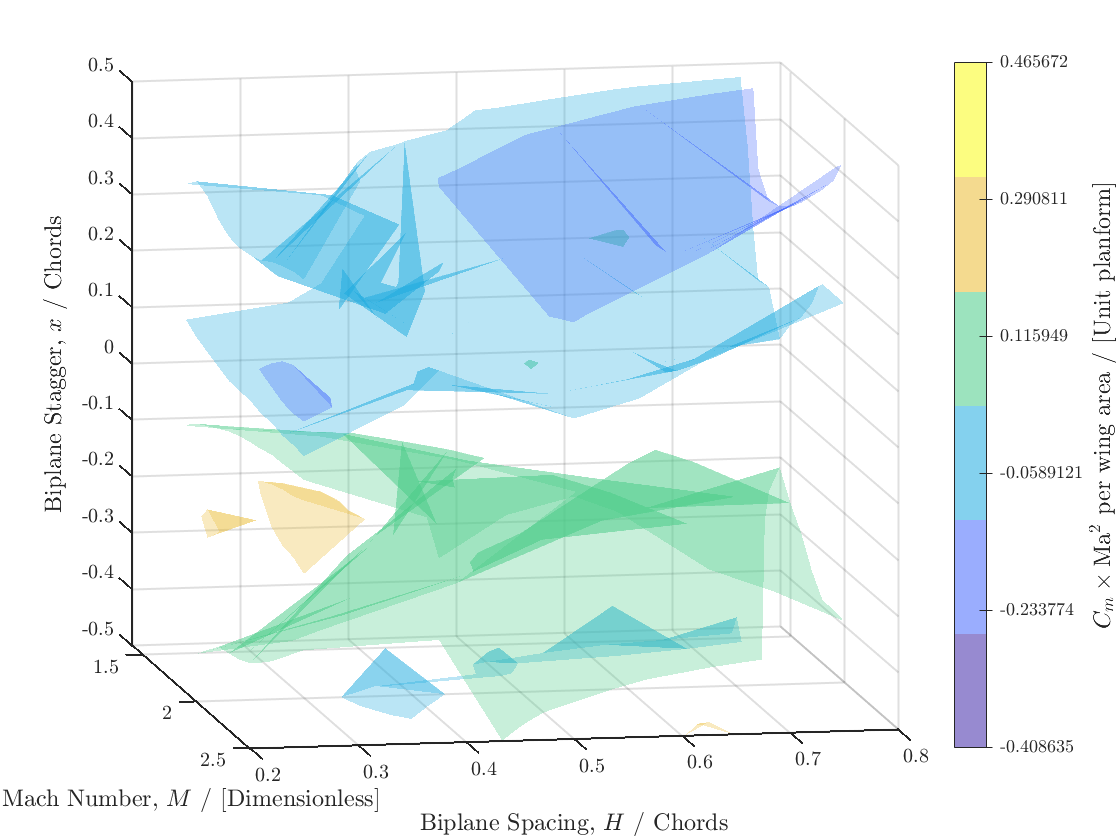

% Visualize the result

number_colors=6;

figure;%clf;
numcolours = number_colors; color = parula(numcolours); %color = jet(N);
lower_index=min(cmMa2,[],'all'); upper_index=max(cmMa2,[],'all');
%levels = logspace(log10(lower_index),log10(upper_index),numcolours);
levels = linspace(lower_index,upper_index,numcolours);
% set(gcf,'Visible','on')
hold on; alfa=0.3;
for i = 1:numcolours
    p = patch(isosurface(X,Y,Z,cmMa2,levels(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    alfa);
    isonormals(X,Y,Z,cmMa2,p)
end
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle); grid on
%camlight('top')%headlight
lighting gouraud
%colormap(parula(numcolours));
%set(gca,'ColorScale','log')
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both','Ticks',linspace(0,1,numcolours),'TickLabels',levels)%,'Limits'),[lower_index,upper_index])
%c.Ruler.Scale='log'
fudge = 1.8; alfa =fudge*alfa; %make it a bit darker for visuals
c.Colormap=((alfa*color)+((1-alfa)*[1,1,1]));
ylabel(c,'$C_{m}\times\textrm{Ma}^2$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
%%title({'$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x$','\textbf{For constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
%title({'$C_{m}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
%%legend('$C_{m}\times\textrm{Ma}^2, \alpha=1^{\circ}$','Location','best')
H=gca; H.LineWidth=1; hold off
saveas(gcf,'alfa1_cmMa2_surf.png')

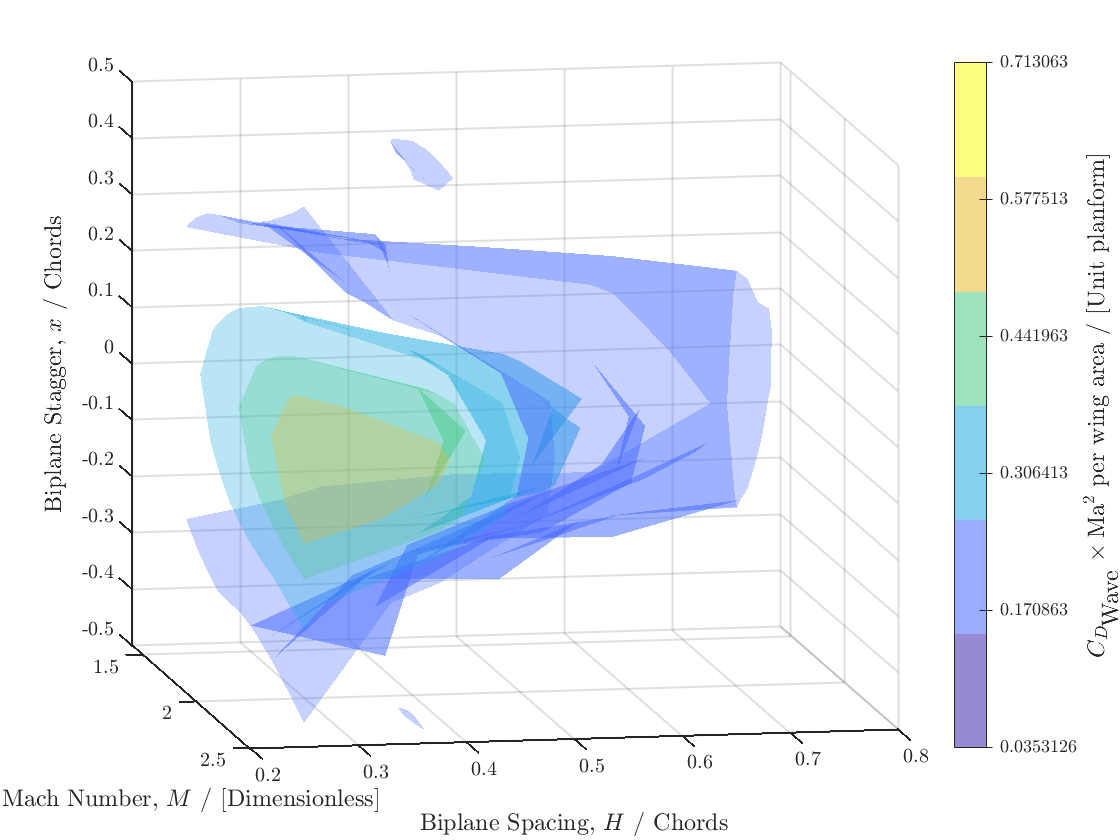


figure;%clf;
numcolours = number_colors; color = parula(numcolours); %color = jet(N);
lower_index=min(cdMa2,[],'all'); upper_index=max(cdMa2,[],'all');
%levels = logspace(log10(lower_index),log10(upper_index),numcolours);
levels = linspace(lower_index,upper_index,numcolours);
% set(gcf,'Visible','on')
hold on; alfa=0.3;
for i = 1:numcolours
    p = patch(isosurface(X,Y,Z,cdMa2,levels(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    alfa);
    isonormals(X,Y,Z,cdMa2,p)
end
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle); grid on
%camlight('top')%headlight
lighting gouraud
%colormap(parula(numcolours));
%set(gca,'ColorScale','log')
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both','Ticks',linspace(0,1,numcolours),'TickLabels',levels)%,'Limits'),[lower_index,upper_index])
%c.Ruler.Scale='log'
fudge = 1.8; alfa =fudge*alfa; %make it a bit darker for visuals
c.Colormap=((alfa*color)+((1-alfa)*[1,1,1]));
ylabel(c,'$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
%%title({'$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x$','\textbf{For constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
%title({'$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
%%legend('$C_{D_\textrm{Wave}}\times\textrm{Ma}^2, \alpha=1^{\circ}$','Location','best')
H=gca; H.LineWidth=1; hold off
saveas(gcf,'alfa1_cdMa2_surf.png')

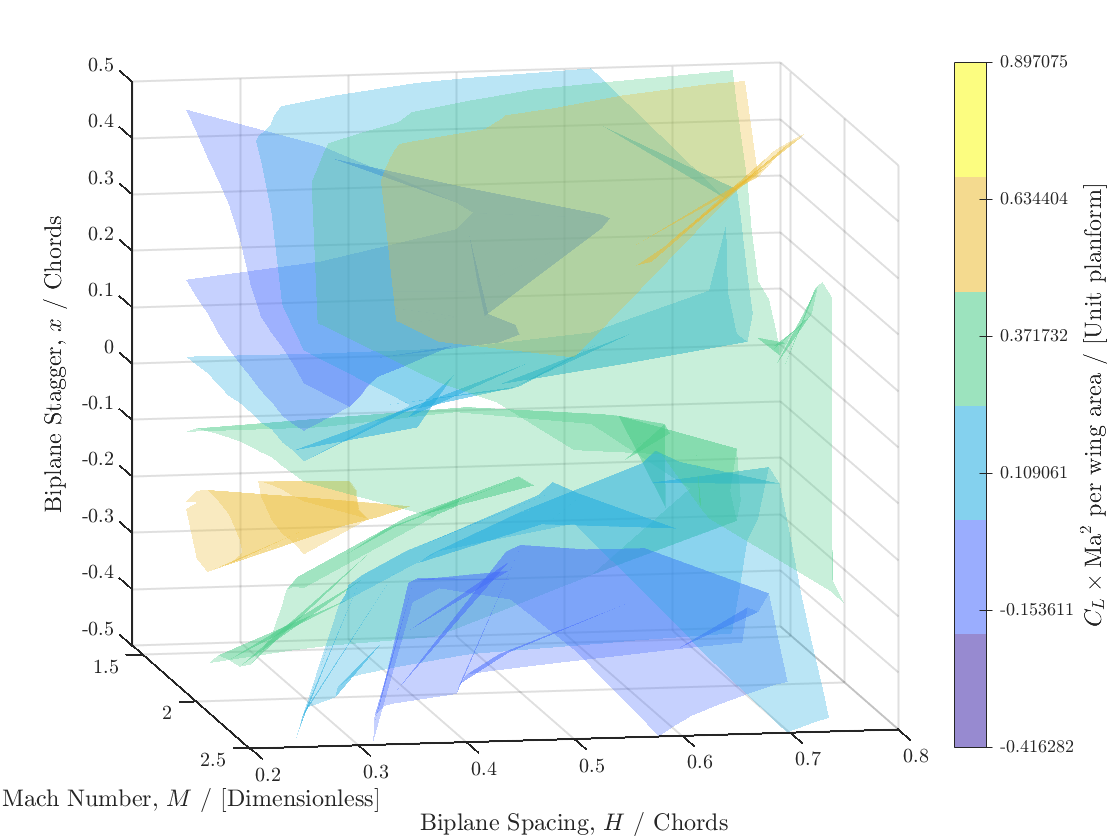


figure;%clf;
numcolours = number_colors; color = parula(numcolours); %color = jet(N);
lower_index=min(clMa2,[],'all'); upper_index=max(clMa2,[],'all');
%levels = logspace(log10(lower_index),log10(upper_index),numcolours);
levels = linspace(lower_index,upper_index,numcolours);
% set(gcf,'Visible','on')
hold on; alfa=0.3;
for i = 1:numcolours
    p = patch(isosurface(X,Y,Z,clMa2,levels(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    alfa);
    isonormals(X,Y,Z,clMa2,p)
end
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle); grid on
%camlight('top')%headlight
lighting gouraud
%colormap(parula(numcolours));
%set(gca,'ColorScale','log')
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both','Ticks',linspace(0,1,numcolours),'TickLabels',levels)%,'Limits'),[lower_index,upper_index])
%c.Ruler.Scale='log'
fudge = 1.8; alfa =fudge*alfa; %make it a bit darker for visuals
c.Colormap=((alfa*color)+((1-alfa)*[1,1,1]));
ylabel(c,'$C_{L}\times\textrm{Ma}^2$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
%title({'$C_{L}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
%%legend('$C_{L_\textrm{Wave}}\times\textrm{Ma}^2, \alpha=1^{\circ}$','Location','best')
H=gca; H.LineWidth=1; hold off
saveas(gcf,'alfa1_clMa2_surf.png')

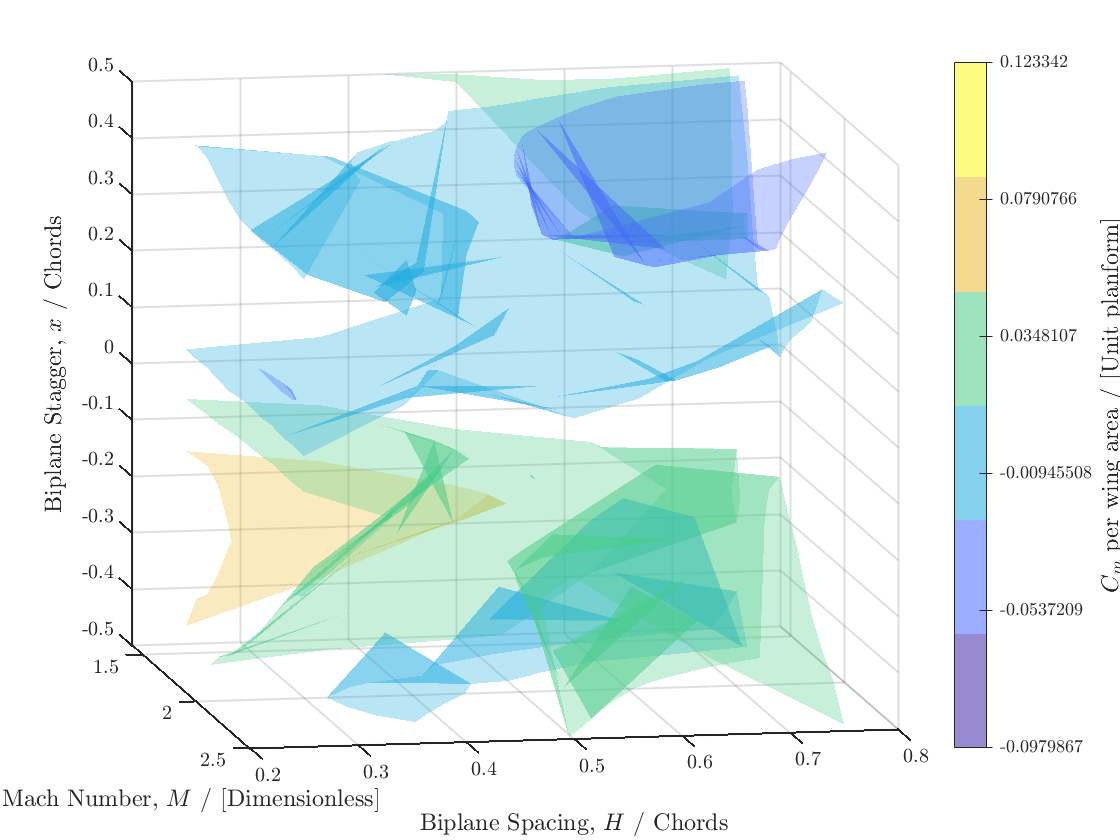


figure;%clf;
numcolours = number_colors; color = parula(numcolours); %color = jet(N);
lower_index=min(cm,[],'all'); upper_index=max(cm,[],'all');
%levels = logspace(log10(lower_index),log10(upper_index),numcolours);
levels = linspace(lower_index,upper_index,numcolours);
% set(gcf,'Visible','on')
hold on; alfa=0.3;
for i = 1:numcolours
    p = patch(isosurface(X,Y,Z,cm,levels(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    alfa);
    isonormals(X,Y,Z,cm,p)
end
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle); grid on
%camlight('top')%headlight
lighting gouraud
%colormap(parula(numcolours));
%set(gca,'ColorScale','log')
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both','Ticks',linspace(0,1,numcolours),'TickLabels',levels)%,'Limits'),[lower_index,upper_index])
%c.Ruler.Scale='log'
fudge = 1.8; alfa =fudge*alfa; %make it a bit darker for visuals
c.Colormap=((alfa*color)+((1-alfa)*[1,1,1]));
ylabel(c,'$C_{m}$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
%title({'\textbf{Moment Coefficient} $C_{m}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
%%legend('$C_{m}, \alpha=1^{\circ}$','Location','best')
H=gca; H.LineWidth=1; hold off
saveas(gcf,'alfa1_cm_surf.png')

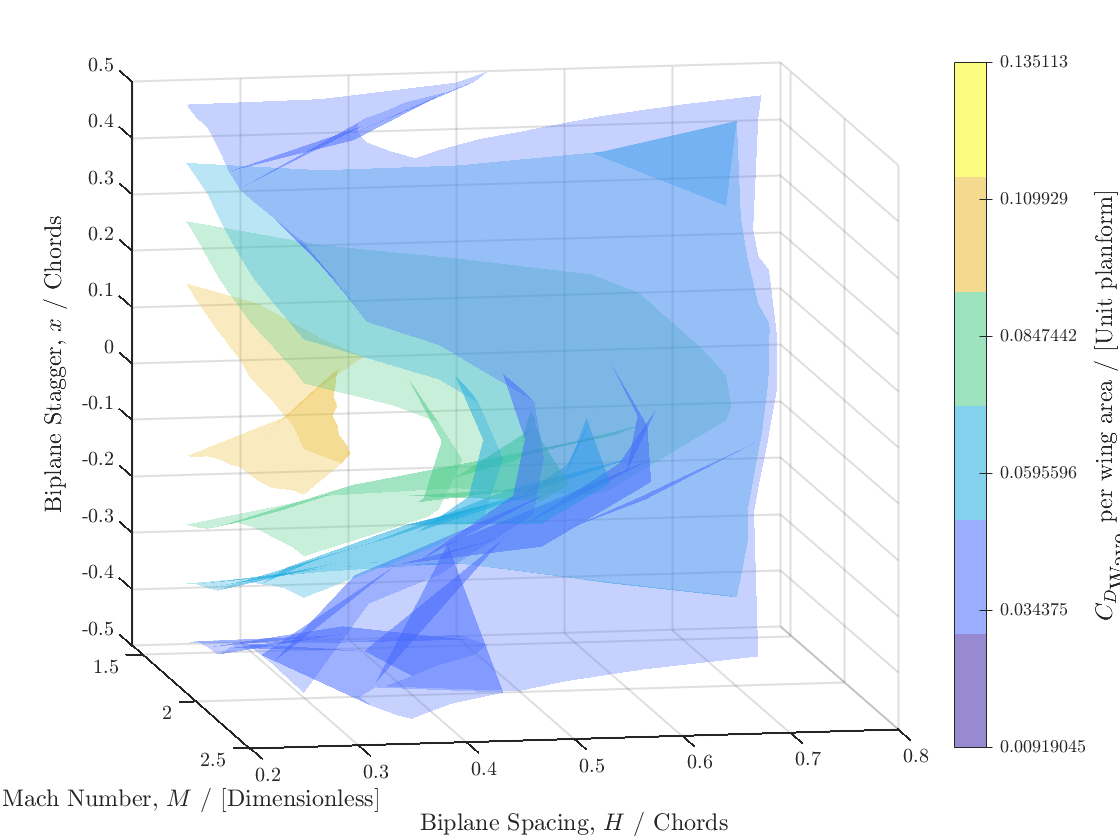


figure;%clf;
numcolours = number_colors; color = parula(numcolours); %color = jet(N);
lower_index=min(cd,[],'all'); upper_index=max(cd,[],'all');
%levels = logspace(log10(lower_index),log10(upper_index),numcolours);
levels = linspace(lower_index,upper_index,numcolours);
% set(gcf,'Visible','on')
hold on; alfa=0.3;
for i = 1:numcolours
    p = patch(isosurface(X,Y,Z,cd,levels(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    alfa);
    isonormals(X,Y,Z,cd,p)
end
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle); grid on
%camlight('top')%headlight
lighting gouraud
%colormap(parula(numcolours));
%set(gca,'ColorScale','log')
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both','Ticks',linspace(0,1,numcolours),'TickLabels',levels)%,'Limits'),[lower_index,upper_index])
%c.Ruler.Scale='log'
fudge = 1.8; alfa =fudge*alfa; %make it a bit darker for visuals
c.Colormap=((alfa*color)+((1-alfa)*[1,1,1]));
ylabel(c,'$C_{D_\textrm{Wave}}$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
%title({'\textbf{Wave Drag Coefficient} $C_{D_\textrm{Wave}}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
%%legend('$C_{D_\textrm{Wave}}, \alpha=1^{\circ}$','Location','best')
H=gca; H.LineWidth=1; hold off
saveas(gcf,'alfa1_cd_surf.png')

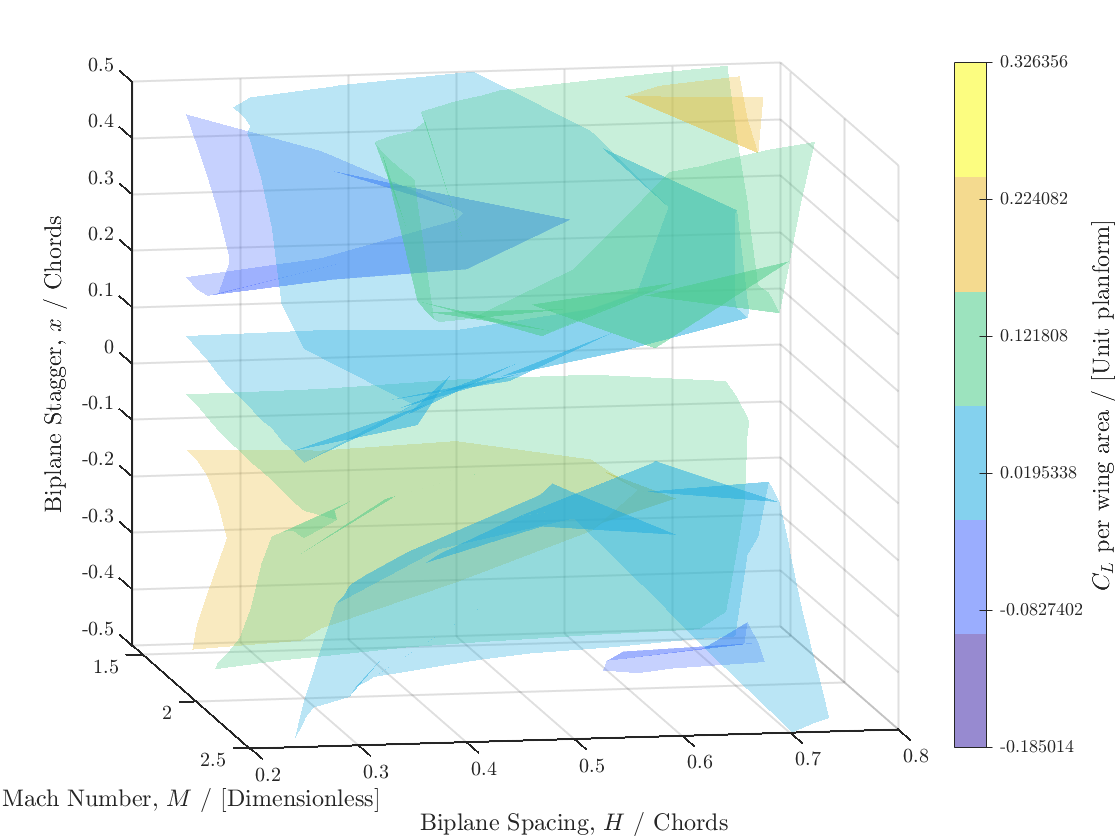


figure;%clf;
numcolours = number_colors; color = parula(numcolours); %color = jet(N);
lower_index=min(cl,[],'all'); upper_index=max(cl,[],'all');
%levels = logspace(log10(lower_index),log10(upper_index),numcolours);
levels = linspace(lower_index,upper_index,numcolours);
% set(gcf,'Visible','on')
hold on; alfa=0.3;
for i = 1:numcolours
    p = patch(isosurface(X,Y,Z,cl,levels(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    alfa);
    isonormals(X,Y,Z,cl,p)
end
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle); grid on
%camlight('top')%headlight
lighting gouraud
%colormap(parula(numcolours));
%set(gca,'ColorScale','log')
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both','Ticks',linspace(0,1,numcolours),'TickLabels',levels)%,'Limits'),[lower_index,upper_index])
%c.Ruler.Scale='log'
fudge = 1.8; alfa =fudge*alfa; %make it a bit darker for visuals
c.Colormap=((alfa*color)+((1-alfa)*[1,1,1]));
ylabel(c,'$C_{L}$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
%title({'\textbf{Lift Coefficient} $C_{L}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
%%legend('$C_{L}, \alpha=1^{\circ}$','Location','best')
H=gca; H.LineWidth=1; hold off
saveas(gcf,'alfa1_cl_surf.png')

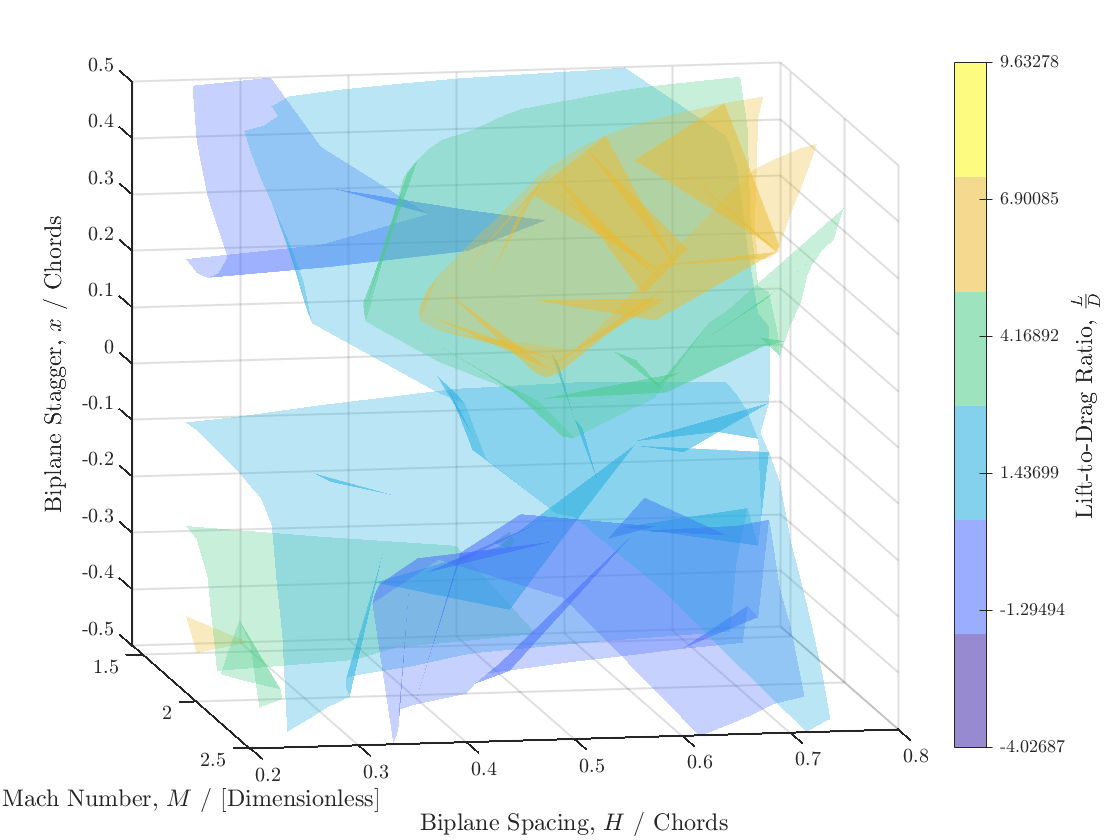


figure;%clf;
numcolours = number_colors; color = parula(numcolours); %color = jet(N);
lower_index=min(LoverD,[],'all'); upper_index=max(LoverD,[],'all');
%levels = logspace(log10(lower_index),log10(upper_index),numcolours);
levels = linspace(lower_index,upper_index,numcolours);
% set(gcf,'Visible','on')
hold on; alfa=0.3;
for i = 1:numcolours
    p = patch(isosurface(X,Y,Z,LoverD,levels(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    alfa);
    isonormals(X,Y,Z,LoverD,p)
end
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle); grid on
%camlight('top')%headlight
lighting gouraud
%colormap(parula(numcolours));
%set(gca,'ColorScale','log')
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both','Ticks',linspace(0,1,numcolours),'TickLabels',levels)%,'Limits'),[lower_index,upper_index])
%c.Ruler.Scale='log'
fudge = 1.8; alfa =fudge*alfa; %make it a bit darker for visuals
c.Colormap=((alfa*color)+((1-alfa)*[1,1,1]));
ylabel(c,'Lift-to-Drag Ratio, $\frac{L}{D}$','Interpreter','latex','FontSize',lsize)
%title({'\textbf{Lift-to-Drag Ratio} $\frac{L}{D}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=1^{\circ}$'},'FontSize',tsize)
%%legend('$\frac{L}{D}, \alpha=1^{\circ}$','Location','best')
H=gca; H.LineWidth=1; hold off
saveas(gcf,'alfa1_loverd_surf.png')

function done = FancyScatter3(RequiredAoA,X,Y,Z,Spacings,Staggers,viewangle)
for a =1:length(Spacings)
for b =1:length(Staggers)
scatter3(X(a,:,b),Y(a,:,b),Z(a,:,b),40,RequiredAoA(a,:,b),'filled')    % draw the scatter plot
hold on
end 
end
grid on; box on; hold on
view(viewangle)
H=gca; H.LineWidth=1; hold off
done = 1;
end

function done = FancyScatter3s(started_drag,X,Y,Z,Spacings,Staggers,viewangle)
for a =1:length(Spacings)
for b =1:length(Staggers)
scatter3(X(a,:,b),Y(a,:,b),Z(a,:,b),40,started_drag(a,:,b),'filled')    % draw the scatter plot
hold on
end 
end
grid on; box on; hold on
view(viewangle)
H=gca; H.LineWidth=1; hold off
done = 1;
end

function done = FancyScatter3c(choked_drag,X,Y,Z,Spacings,Staggers,viewangle,width)
for a =1:length(Spacings)
for b =1:length(Staggers)
scatter3(X(a,:,b),Y(a,:,b),Z(a,:,b),50,choked_drag(a,:,b),'x','LineWidth',width)    % draw the scatter plot
hold on
end 
end
grid on; box on; hold on
view(viewangle)
H=gca; H.LineWidth=1; hold off
done = 1;
end

function [SubsequentCD_3s,SubsequentCD_3c,started_locations,choked_locations] = cd_isstarted(SubsequentCD_3,cutoff)
[started_locations,choked_locations]=ischoked(SubsequentCD_3,cutoff);
SubsequentCD_3c=SubsequentCD_3.*choked_locations;
SubsequentCD_3c(SubsequentCD_3c==0)=NaN;
SubsequentCD_3s=SubsequentCD_3.*started_locations;
SubsequentCD_3s(SubsequentCD_3s==0)=NaN;
end

function [started_locations,choked_locations]=ischoked(SubsequentCD_3,cutoff)
choked_locations = SubsequentCD_3 >= cutoff;
started_locations = 1-choked_locations;
end

function [SubsequentCDMa2s,SubsequentCDMa2c]=splitmatrix(SubsequentCDMa2,started_locations,choked_locations)
SubsequentCDMa2c=SubsequentCDMa2.*choked_locations;
SubsequentCDMa2c(SubsequentCDMa2c==0)=NaN;
SubsequentCDMa2s=SubsequentCDMa2.*started_locations;
SubsequentCDMa2s(SubsequentCDMa2s==0)=NaN;
end
